# Orbital Process Noise

% Sets the initial orbital elements and other simulation parameters
planet_radius = 6378E3;
earth_mass = 5.974E24;

grav_const = 6.67430E-11;
grav_param = grav_const * earth_mass;

orbit_param = struct;
orbit_param.semi_major = planet_radius + 100E3;
orbit_param.eccen = 0.01;
orbit_param.inclin_deg = 50;
orbit_param.raan_deg = 95;
orbit_param.arg_periapse_deg = 93;
orbit_param.true_anom_deg = 203;

% Run the simulation
sim_time = 9*3600;
warning('off', 'all')
orbit_process_noise_sim = sim('orbit_process_noise', StopTime=num2str(sim_time));

unpert_pos = orbit_process_noise_sim.unpert_pos.Data;
unpert_vel = orbit_process_noise_sim.unpert_vel.Data;
pert_pos = orbit_process_noise_sim.pert_pos.Data;
pert_vel = orbit_process_noise_sim.pert_vel.Data;

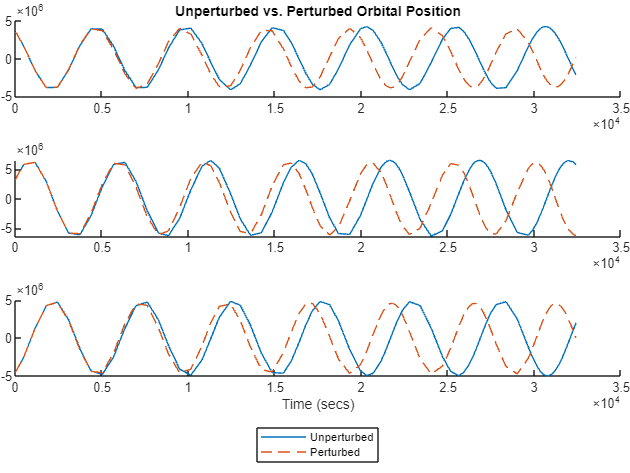

figure
tiledlayout(3, 1, "Padding","tight", "TileSpacing","compact")

nexttile
hold on
plot(orbit_process_noise_sim.tout, unpert_pos(:, 1))
plot(orbit_process_noise_sim.tout, pert_pos(:, 1), '--')
title('Unperturbed vs. Perturbed Orbital Position')

nexttile
hold on
plot(orbit_process_noise_sim.tout, unpert_pos(:, 2))
plot(orbit_process_noise_sim.tout, pert_pos(:, 2), '--')

nexttile
hold on
plot(orbit_process_noise_sim.tout, unpert_pos(:, 3))
plot(orbit_process_noise_sim.tout, pert_pos(:, 3), '--')
legend('Unperturbed', 'Perturbed',  'Location', 'southoutside')
xlabel('Time (secs)')

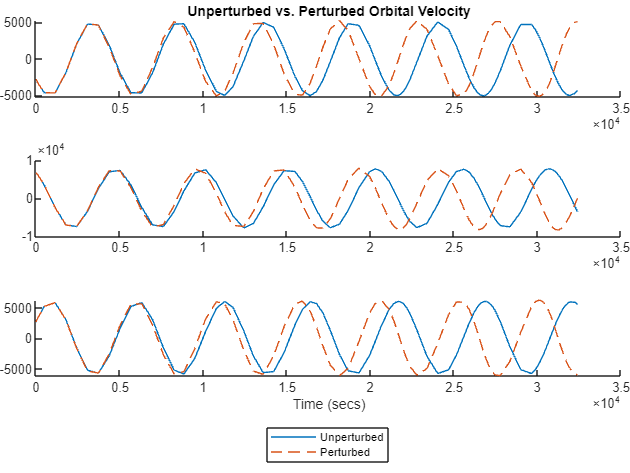


figure
tiledlayout(3, 1, "Padding","tight", "TileSpacing","compact")

nexttile
hold on
plot(orbit_process_noise_sim.tout, unpert_vel(:, 1))
plot(orbit_process_noise_sim.tout, pert_vel(:, 1), '--')
title('Unperturbed vs. Perturbed Orbital Velocity')

nexttile
hold on
plot(orbit_process_noise_sim.tout, unpert_vel(:, 2))
plot(orbit_process_noise_sim.tout, pert_vel(:, 2), '--')

nexttile
hold on
plot(orbit_process_noise_sim.tout, unpert_vel(:, 3))
plot(orbit_process_noise_sim.tout, pert_vel(:, 3), '--')
legend('Unperturbed', 'Perturbed',  'Location', 'southoutside')
xlabel('Time (secs)')

% Considers the process noise to be the difference between the perturbed
% and unperturbed orbits (due to perturbing effects)
noise_pos = pert_pos ./ unpert_pos;
noise_vel = pert_vel ./ unpert_vel;

noise = [noise_pos noise_vel];

% Computes the covariance of the "noise" to be used with the EKF for better
% accuracy of the process noise
orbit_process_noise_cov = cov(noise);

save('navigation/orbital-determination/ekf/orbit_process_noise', 'orbit_process_noise_cov')